# "How to load data": (Example of scenario 1)


%  The HDF-5 file stores **one row per Wi-Fi packet**.  The main integer columns let you
%  slice the big table quickly:
%
%      ▸ room_id     : 0 → Room A   ·  1 → Room B
%      ▸ setting_id  : 0 → ‘_1’     ·  1 → ‘_2’
%      ▸ pkt_idx     : running index *within* each (room,setting) trace
%      ▸ seg_idx     : 0 … 149  (150 two-second windows per trace)
%
%  All other datasets share the first dimension:
%      td_us – micro-second time-stamp (int64)
%      rssi  – [N,2] float32   ·  mcs – uint8
%      gain  – [N,2] complex64 ·  csi – [N,subc,ant] complex64
%
%  MATLAB’s HDF-5 interface reads native complex automatically.  A quick
%  peek at the structure:
h5disp("packets_scenario_1.h5","/")

HDF5 packets_scenario_1.h5 
Group '/' 
    Dataset 'csi' 
        Size:  4x250x26821
        MaxSize:  4x250x26821
        Datatype:   H5T_COMPOUND
            Member 'r':  H5T_IEEE_F32LE (single)
            Member 'i':  H5T_IEEE_F32LE (single)
        ChunkSize:  1x16x839
        Filters:  shuffle, deflate(4)
        FillValue:  H5T_COMPOUND
    Dataset 'gain' 
        Size:  2x26821
        MaxSize:  2x26821
        Datatype:   H5T_COMPOUND
            Member 'r':  H5T_IEEE_F32LE (single)
            Member 'i':  H5T_IEEE_F32LE (single)
        ChunkSize:  1x1677
        Filters:  shuffle, deflate(4)
        FillValue:  H5T_COMPOUND
    Dataset 'mcs' 
        Size:  26821
        MaxSize:  26821
        Datatype:   H5T_STD_U8LE (uint8)
        ChunkSize:  6706
        Filters:  shuffle, deflate(4)
        FillValue:  0
    Dataset 'pkt_idx' 
        Size:  26821
        MaxSize:  26821
        Datatype:   H5T_STD_I32LE (int32)
        ChunkSize:  1677
        Filters:  shuffle, defl

## 1.  Load the index columns (cheap – they are uint / int64)

room_id   = h5read("packets_scenario_1.h5","/room_id");      % [N  ] uint8
setting_id= h5read("packets_scenario_1.h5","/setting_id");   % [N  ] uint8
pkt_idx   = h5read("packets_scenario_1.h5","/pkt_idx");      % [N  ] int32
seg_idx   = h5read("packets_scenario_1.h5","/seg_idx");      % [N  ] int32


## 2.  Choose a **room / setting / segment** of interest

% Different segments have a different number of packets
ROOM    = 0;      % 0 → Room A , 1 → Room B
SETTING = 1;      % 0 → “_1”   , 1 → “_2”
SEGMENT =  140;    % 0 … 149

sel = (room_id   == ROOM   ) & ...
      (setting_id== SETTING) & ...
      (seg_idx   == SEGMENT);

% number of packets inside this 2-s window
n_pkts = nnz(sel);
fprintf("Segment %d of Room %d / Setting %d has %d packets\n", ...
        SEGMENT, ROOM, SETTING, n_pkts)

Segment 140 of Room 0 / Setting 1 has 46 packets


## 3.  Read *only those packets* for each variable

read_sel = @(path) h5read("packets_scenario_1.h5", path, ...
                          fliplr(find(sel,1,'first')),        ...
                          [nnz(sel); ones( ndims(h5info("packets_scenario_1.h5",path).Dataspace.Size)-1 ,1)]);

td_us = h5read("packets_scenario_1.h5","/td_us");
td_us = td_us(sel);                       % micro-second time-stamps

rssi  = h5read("packets_scenario_1.h5","/rssi");   rssi  = rssi(:,sel).';   % [n_pkts,2]
mcs   = h5read("packets_scenario_1.h5","/mcs");    mcs   = mcs(sel);        % [n_pkts,1]

gain  = h5read("packets_scenario_1.h5","/gain");                           % struct → complex
gain  = complex(gain.r, gain.i);        gain  = gain(:,sel).';

csi   = h5read("packets_scenario_1.h5","/csi");                            % [250,4, N] or [248,4, N]
csi = complex(csi.r(:,:,sel), csi.i(:,:,sel));
% csi

## 4.  Quick visual sanity check

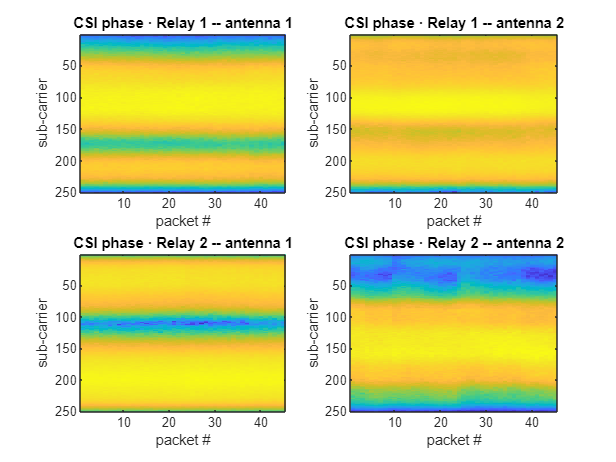

figure
subplot(2,2,1)
csi_db_1 = 20*log10(abs(squeeze(csi(1, :, :))));
imagesc(csi_db_1)        % unwrap first antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 1 -- antenna 1')
subplot(2,2,2)
csi_db_2 = 20*log10(abs(squeeze(csi(2, :, :))));
imagesc(csi_db_2)        % unwrap the second antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 1 -- antenna 2')

subplot(2,2,3)
csi_db_3 = 20*log10(abs(squeeze(csi(3, :, :))));
imagesc(csi_db_3)        % unwrap first antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 2 -- antenna 1')
subplot(2,2,4)
csi_db_4 = 20*log10(abs(squeeze(csi(4, :, :))));
imagesc(csi_db_4)        % unwrap the second antenna
xlabel('packet #'), ylabel('sub-carrier')
title('CSI phase · Relay 2 -- antenna 2')

## 5. Loading labels for each segment

h5disp('segments_scenario_1.h5','/')

HDF5 segments_scenario_1.h5 
Group '/' 
    Dataset 'seg_len' 
        Size:  600
        MaxSize:  600
        Datatype:   H5T_STD_U16LE (uint16)
        ChunkSize:  600
        Filters:  shuffle, deflate(6)
        FillValue:  0
    Dataset 'seg_ptr' 
        Size:  601
        MaxSize:  601
        Datatype:   H5T_STD_I64LE (int64)
        ChunkSize:  601
        Filters:  shuffle, deflate(6)
        FillValue:  0
    Group '/labels' 
        Dataset 'parlor' 
            Size:  300
            MaxSize:  300
            Datatype:   H5T_STD_I16LE (int16)
            ChunkSize:  300
            Filters:  shuffle, deflate(6)
            FillValue:  0
        Dataset 'roomA' 
            Size:  300
            MaxSize:  300
            Datatype:   H5T_STD_I16LE (int16)
            ChunkSize:  300
            Filters:  shuffle, deflate(6)
            FillValue:  0
        Dataset 'roomB' 
            Size:  300
            MaxSize:  300
            Datatype:   H5T_STD_I16LE (int16)
     


seg_ptr = h5read('segments_scenario_1.h5','/seg_ptr');   % int64, size [S+1]
seg_len = h5read('segments_scenario_1.h5','/seg_len');   % uint16, size [S]

lbl_parlor = h5read('segments_scenario_1.h5','/labels/parlor'); % int16, [S]
lbl_roomA  = h5read('segments_scenario_1.h5','/labels/roomA');  % int16
lbl_roomB  = h5read('segments_scenario_1.h5','/labels/roomB');  % int16

% To get the specific labels for the SEGMENT and SETTING we chosed before
S = numel(lbl_parlor)/2;          % = 150
idx = SETTING*S + SEGMENT + 1;       % MATLAB is 1-based

y_parlor = lbl_parlor(idx);
y_roomA  = lbl_roomA(idx);
y_roomB  = lbl_roomB(idx);

fprintf('Labels [Parlor, Room A, Room B] = [%d, %d, %d]\n', ...
        lbl_parlor(idx), lbl_roomA(idx), lbl_roomB(idx));

Labels [Parlor, Room A, Room B] = [0, 0, 0]


## 6. Plotting the Room A CSIs for segments have different number of people

% Plot CSI (first two antennas) for Room A segments with labels 0,1,2
% We choose the second setting (with interference)

labels_roomA  = h5read('segments_scenario_1.h5','/labels/roomA');  % int16

ROOM    = 0;    % Room A
SETTING = 1;    % 0 → “_1”, 1 → “_2”
want_labels = [0 1 2];

num_settings = 2;
S = numel(labels_roomA) / num_settings;
S = round(S);
% --- labels for chosen SETTING (length S) ---
idx0 = SETTING * S + 1;        % MATLAB 1-based
idx1 = (SETTING + 1) * S;
labels_this = labels_roomA(idx0:idx1);
% --- pick one segment id for each label in want_labels ---
seg_pick = nan(size(want_labels));
for k = 1:numel(want_labels)
    hit = find(labels_this == want_labels(k), 1, 'first');
    if ~isempty(hit)
        seg_pick(k) = hit - 1;
    else
        fprintf('Warning: no Room A segment with label %d in setting %d.\n', ...
                 want_labels(k), SETTING);
    end
end

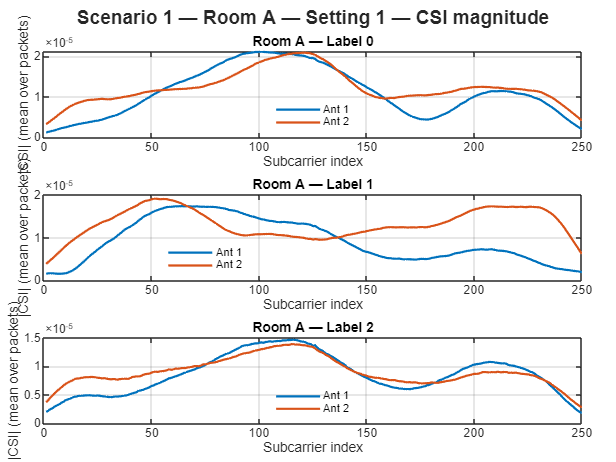


useAnt = 2;
csi   = h5read("packets_scenario_1.h5","/csi");                            % [250,4, N] or [248,4, N]

tiledlayout(3,1, 'TileSpacing','compact', 'Padding','compact');

for k = 1:numel(want_labels)
    nexttile;
    seg_k = seg_pick(k);

    if isnan(seg_k)
        title(sprintf('Label = %d (not found)', want_labels(k)), 'FontWeight','bold');
        axis off; continue;
    end

    % packets for this Room/Setting/Segment
    sel = (room_id == ROOM) & (setting_id == SETTING) & (seg_idx == seg_k);
    n_pkts = nnz(sel);
    if n_pkts == 0
        title(sprintf('Label = %d (no packets)', want_labels(k)), 'FontWeight','bold');
        axis off; continue;
    end

    csi_seg = complex(csi.r(:,:,sel), csi.i(:,:,sel));    
    % mean magnitude over packets → (Ant, Sub)
    mean_mag = squeeze(mean(abs(csi_seg), 3)).'; % (Sub, Ant)
    [nSub, nAnt] = size(mean_mag);
    
    plot(1:nSub, mean_mag(:,1), 'LineWidth', 1.5); hold on;
    if useAnt >= 2
        plot(1:nSub, mean_mag(:,2), 'LineWidth', 1.5);
        legend({'Ant 1','Ant 2'}, 'Location','best'); legend boxoff;
    else
        legend({'Ant 1'}, 'Location','best'); legend boxoff;
    end
    grid on;
    xlabel('Subcarrier index');
    ylabel('|CSI| (mean over packets)');
    title(sprintf('Room A — Label %d', want_labels(k)));
end

sgtitle(sprintf('Scenario 1 — Room A — Setting %d — CSI magnitude', ...
         SETTING), 'FontWeight','bold');